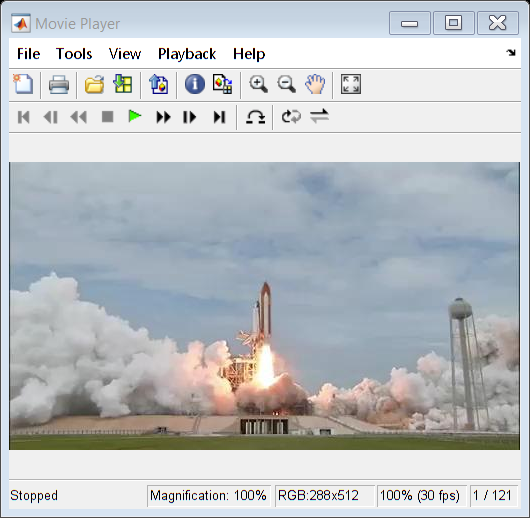

video =   UnifiedScope with properties:

    InstanceNumber: 1
     Specification: [1×1 iptscopes.IMPlayScopeCfg]
        MessageLog: []
            Visual: [1×1 iptscopes.VideoVisual]
        DataSource: [1×1 matlabshared.scopes.source.FileSource]
            Parent: [1×1 Figure]


video = implay("shuttle.avi")

Let's remove the frames from 119 to the end because they are taken from another angle

vIn = VideoReader("shuttle.avi")

vIn =   VideoReader with properties:

   General Properties:
            Name: 'shuttle.avi'
            Path: 'C:\Program Files\MATLAB\R2022b\toolbox\matlab\demos'
        Duration: 4.0333
     CurrentTime: 0
       NumFrames: 121

   Video Properties:
           Width: 512
          Height: 288
       FrameRate: 30
    BitsPerPixel: 24
     VideoFormat: 'RGB24'


numFrames_vIn = vIn.NumFrames;
vOut = VideoWriter("new_shuttle.avi","MPEG-4");
Frames_to_remove = 3;
vOut.FrameRate = vIn.FrameRate;
open(vOut);
for i = 1 : (numFrames_vIn - Frames_to_remove)
    frame = readFrame(vIn);
    writeVideo(vOut,frame);
end
close(vOut);

v_toProcess = VideoReader("new_shuttle.avi.mp4");

Let's extact some frames to create the segmentation function

frame_1 = read(v_toProcess,1);
frame_30 = read(v_toProcess,30);
frame_90 = read(v_toProcess,90);
frame_105 = read(v_toProcess,105);
imwrite(frame_1,"frame_1.jpg");
imwrite(frame_30,"frame_30.jpg");
imwrite(frame_90,"frame_90.jpg");
imwrite(frame_105,"frame_105.jpg");

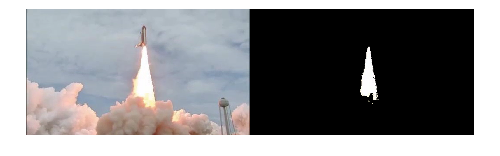

[BW,maskedImage] = segmentImageShuttle(frame_105);
montage({frame_105,maskedImage})

frame_1 = read(v_toProcess,1);
binary_frame_1 = segmentImageShuttle(frame_1);
properties_1 = regionprops(binary_frame_1, {'Area'});
properties_1 = struct2table(properties_1);
region_1 = sum(properties_1.Area);

frame_end = read(v_toProcess,v_toProcess.NumFrames);
binary_frame_end = segmentImageShuttle(frame_end);
properties_end = regionprops(binary_frame_end, {'Area'});
properties_end = struct2table(properties_end);
region_end = sum(properties_end.Area);

region_end/region_1

ans = 5.9132